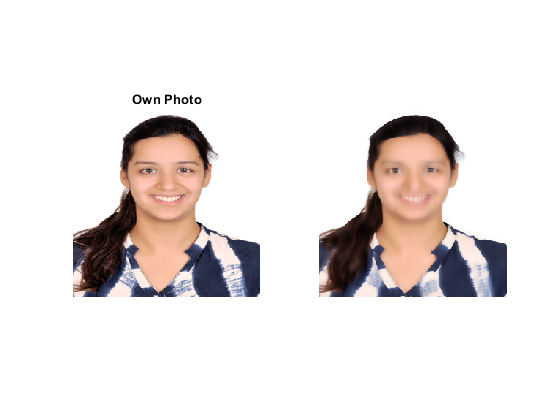

clear;

image1 = imread("https://i.ibb.co/YNZwNzv/Photo.jpg");
image2 = imread("https://i.ibb.co/VqMMCrG/French-Fries.jpg");
image3 = imread("https://i.ibb.co/18VGvNF/Century-Tower.jpg");

BilateralFilter(image1,'Own Photo');

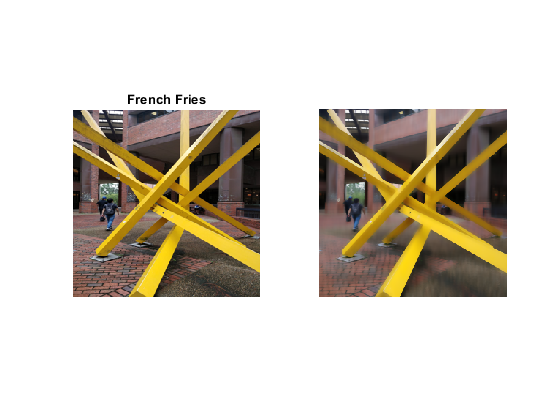

BilateralFilter(image2,'French Fries');

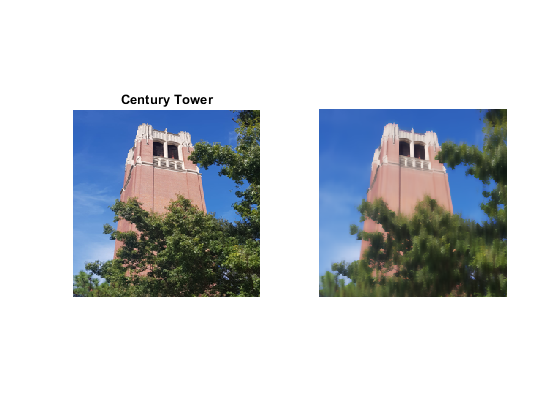

BilateralFilter(image3,'Century Tower');

function BilateralFilter(ImageToFilter,Title)

sizedImage1 = imresize(ImageToFilter,[256 256]);
sizedImage = double(sizedImage1);
[rows, cols, ~] = size(sizedImage);
outputImageMain = zeros(rows,cols,3);

for i = 1 : rows
    for j = 1 : cols

        if(i-5 < 1) kmin = 1; else kmin = i-5; end
        if(i+5 > rows) kmax = rows; else kmax = i+5; end
        if(j-1 < 1) lmin = 1; else lmin = j-1; end
        if(j+1 > cols) lmax = cols; else lmax = j+1; end
                     
        slicedImage = sizedImage(kmin:kmax, lmin:lmax, :);
        % calculating domain kernel
        domainKernel = zeros(11,11);       
        a =1;
        for k = kmin : kmax 
            b=1;
            for l = lmin : lmax                 
                   domainKernel(a,b) = exp(-(((i-k)^2)+((j-l)^2))/(2*8*8));
                   b = b+1;
            end
            a = a+1;
        end
        % interating over the  image with the kernel
        for n = 1 : 3
            distanceMatrix = (slicedImage(:,:,n) - sizedImage(i,j,n)).^2;
            rangeKernel = exp(-(distanceMatrix)/2*0.02*0.02);
            [r,c,~] = size(rangeKernel);
            if(r < 11 || c < 11)
                domainKernel = domainKernel(1:r,1:c);
            end
            weights = domainKernel .* rangeKernel;
            weightSum = sum(weights,'all');
            outputImageMain(i,j,n) = sum((slicedImage(:,:,n) .*weights),'all')/weightSum;                   
        end
       
    end
end
figure();
subplot(1,2,1),imshow(sizedImage1),title(Title);
subplot(1,2,2),imshow(uint8(outputImageMain));
end